Lab Exercise - 10

BL.AI.U4AID25064

Sudarshan Rao

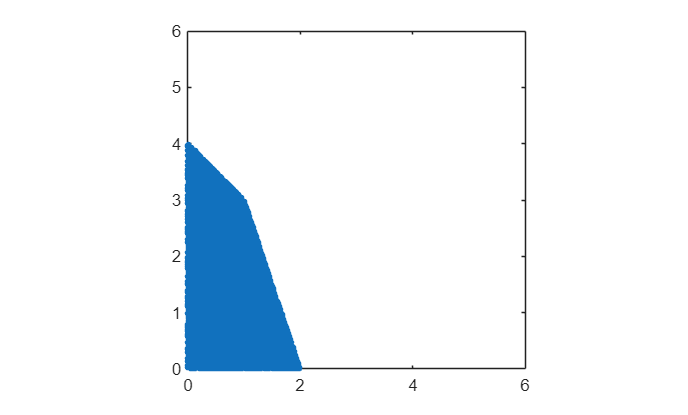

% Example - 1

N=200000; % number (x,y) points in domain
x = rand(N,1)*6; % generates values in (0,6)
y = rand(N,1)*6; % generates values in (0,6)

f1 = x+y-4; % An array of N fn values in domain
ind1 = (f1<0); % An N array of logical 0s and 1s

f2 = 3*x+y-6; % An array of N fn values in domain
ind2 = (f2<0); % An N_array of logical 0s and 1s
ind3=and(ind1,ind2); % An N_array of logical 0s and 1s

a = [x(ind3),y(ind3)];% points which are in feasible region


figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([0 6])
ylim([0 6]) 


%third and forth constarints, x and y are positive are already considered since by using 'rand' 
% command, we randomly generate points only between 0 and 1.

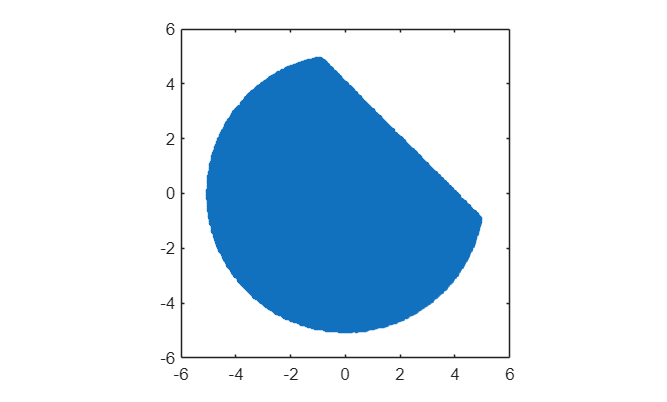

% Example - 2

N=200000; % number (x,y) points in domain
x = -6+12*rand(N,1); % generates values in (-6,6)
y = -6+12*rand(N,1); % generates values in (-6,6)

f1 = x+y-4; % An array of N fn values in domain
ind1 = (f1<0); % An N array of logical 0s and 1s

f2 = x.^2+y.^2-25; % An array of N fn values in domain
ind2 = (f2<0); % An N_array of logical 0s and 1s
ind3=and(ind1,ind2); % An N_array of logical 0s and 1s
a = [x(ind3),y(ind3)];% points which are in feasible region

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-6 6])
ylim([-6 6])

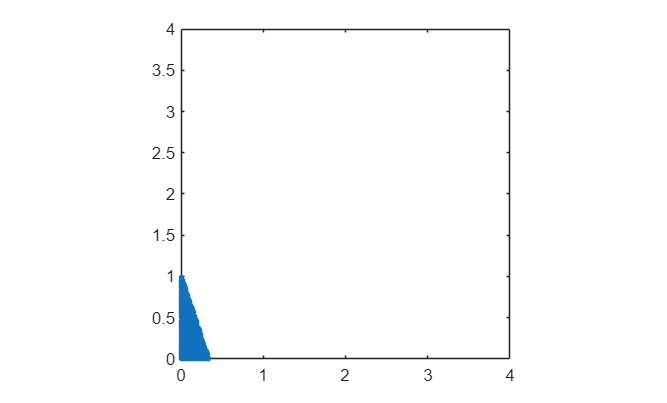

% question - 1
% a
N=200000;

x=rand(N,1)*4;
y=rand(N,1)*4;

f1=3*x+y-1;
ind1=(f1<0);

f2=2*x-3*y-3;
ind2=(f2<0);

ind3=and(ind1,ind2);

a=[x(ind3),y(ind3)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([0 4])
ylim([0 4])

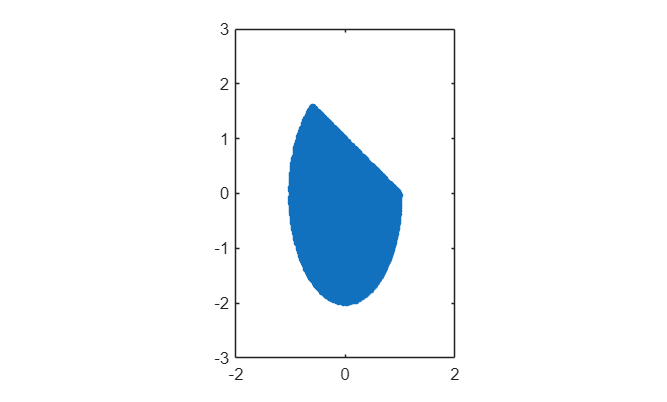


%b
N=200000;

x=-2+4*rand(N,1);
y=-3+6*rand(N,1);

f1=x.^2+(y.^2)/4-1;
ind1=(f1<0);

f2=x+y-1;
ind2=(f2<0);

ind3=and(ind1,ind2);

a=[x(ind3),y(ind3)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-2 2])
ylim([-3 3])

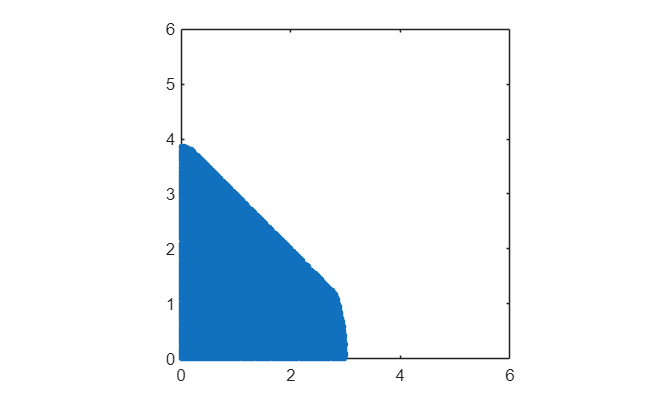


%c
N=200000;

x=rand(N,1)*6;
y=rand(N,1)*6;

f1=x+y-4;
ind1=(f1<0);

f2=2*x+x.^2+y.^2-15;
ind2=(f2<0);

ind3=and(ind1,ind2);

a=[x(ind3),y(ind3)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([0 6])
ylim([0 6])

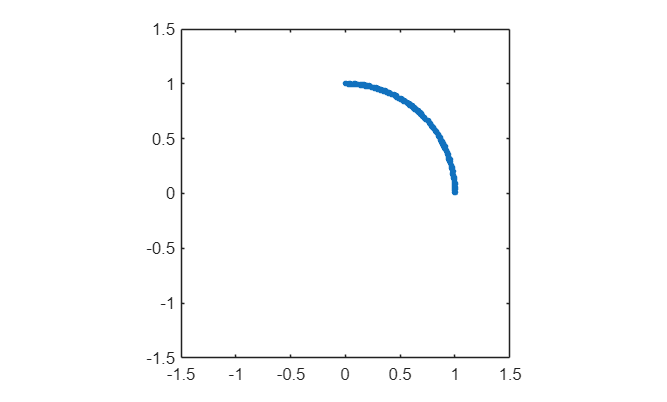


%d
N=200000;

x=-1.5+3*rand(N,1);
y=-1.5+3*rand(N,1);

f1=x.^2+y.^2-1;
ind1=(abs(f1)<0.01);

f2=x+y-1;
ind2=(f2>0);

ind3=and(ind1,ind2);

a=[x(ind3),y(ind3)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-1.5 1.5])
ylim([-1.5 1.5])

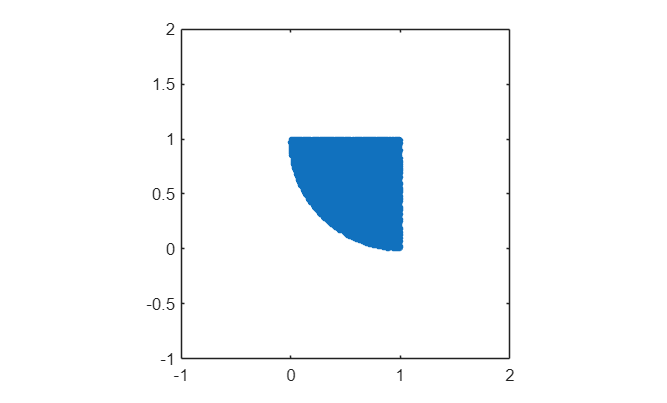


%e
N=200000;

x=-1+3*rand(N,1);
y=-1+3*rand(N,1);

f1=(x-1).^2+(y-1).^2-1;
ind1=(f1<0);

f2=x-1;
ind2=(f2<0);

f3=y-1;
ind3=(f3<0);

ind4=and(ind1,ind2);
ind5=and(ind4,ind3);

a=[x(ind5),y(ind5)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-1 2])
ylim([-1 2])

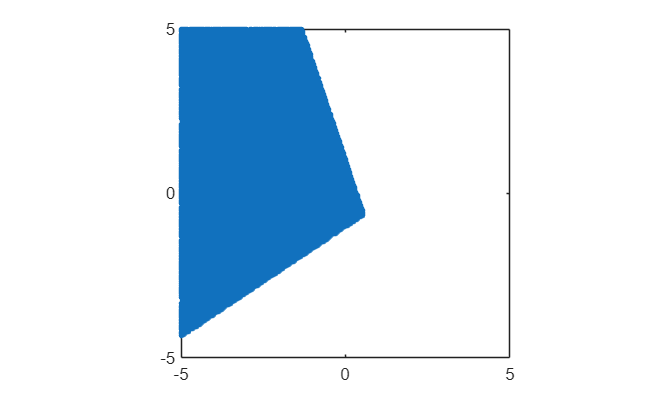

% question - 2
% a
N=200000;

x=-5+10*rand(N,1);
y=-5+10*rand(N,1);

f1=x-y-2;
ind1=(f1<0);

f2=3*x+y-1;
ind2=(f2<0);

f3=2*x-3*y-3;
ind3=(f3<0);

ind4=and(ind1,ind2);
ind5=and(ind4,ind3);

a=[x(ind5),y(ind5)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-5 5])
ylim([-5 5])

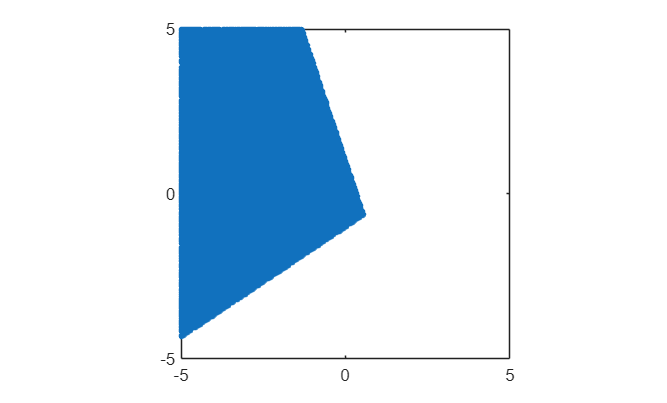


%b 
N=200000;

x=-5+10*rand(N,1);
y=-5+10*rand(N,1);

f1=x-y-2;
ind1=(f1<0);

f2=3*x+y-1;
ind2=(f2<0);

f3=2*x-3*y-3;
ind3=(f3<0);

ind4=and(ind1,ind2);
ind5=and(ind4,ind3);

a=[x(ind5),y(ind5)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-5 5])
ylim([-5 5])

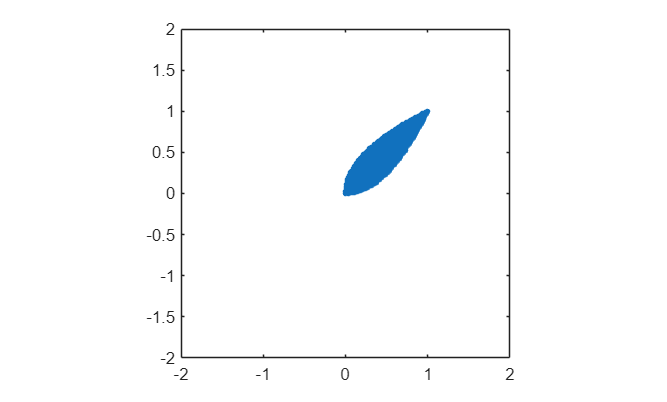


%c
N=200000;

x=-2+4*rand(N,1);
y=-2+4*rand(N,1);

f1=x.^2-y;
ind1=(f1<0);

f2=y.^2-x;
ind2=(f2<0);

ind3=and(ind1,ind2);

a=[x(ind3),y(ind3)];

figure
plot(a(:,1),a(:,2),'.','MarkerSize',10);
axis equal
xlim([-2 2])
ylim([-2 2])